clear all, close all, clc

## Class 05

Here's the deal

P = 250*1e3;        % U-fuel power, W
J_MeV = 1.6e-13;    % Cnv factor
n = 200;            % E production rate; MeV/Fsn

fr = P/J_MeV /n     % fission rate; fsn/s

fr = 7.8125e+15

Now, let's calculate no. of prompt g. We have-

 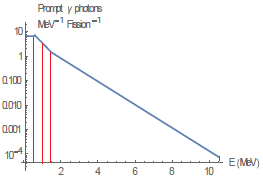

So, we have-

syms E
N_1 = 6.6*E^0;              % 0.1 - 0.6 MeV; no. of prompt g
N_2 = 20.2*exp(-1.78*E);    % 0.6 - 1.5 MeV
N_3 = 7.2*exp(-1.09*E);     % 1.5 - 10.5 MeV

Now, let's find the prompt-g energy-


$$E_{p,\gamma \;} =\int_{0\ldotp 1}^{10\ldotp 5} \;{E\;N}_{\gamma \;} \left(E\right)\;\textrm{dE}$$


Now, let's define the integaral expressions

E_N1 = E*N_1;
E_N2 = E*N_2;
E_N3 = E*N_3;

Now, let's perform the integral-

E_1 = int(E_N1, 0.1, 0.6);   % MeV*#
E_2 = int(E_N2, 0.6, 1.5);
E_3 = int(E_N3, 1.5, 10.5);

Then, the total energy is-

E = E_1 + E_2 + E_3;
E = double(E)               % MeV

E = 7.1783

## Class 07

Given,

syms E
dx = 1;             % Al sheet thickness, cm
  C = 3.47e-4;
  p = 1.73;             % putting a const.
rh_lm = C*E^p;          % range, gm/cm^2

We know, 

rho_A = 2.7;            % Al density; gm/cm^3

Then, we have, range-

alf = C/rho_A          % defining const.

alf = 1.2852e-04

lam = rh_lm/rho_A;      % cm

So, let's find the energy value

    E = 0;
lam_1 = eval(lam)

lam_1 = 0

%
    E = 500;
lam_2 = eval(lam)

lam_2 = 6.0004

Now, let's do the following, 

$L{\left(E\right)}=\frac{dE}{dx}$        % Definition of LET

Or, $dx=\frac{dE}{L\left(E\right)}$

Or, $x_0 -x_i =\textrm{dx}=-\int_{E_i }^{E_0 } \frac{dE}{L{\left(E\right)}}$

Or, $1=-\left\lbrack \Lambda {\left(E_o \right)}-\Lambda {\left(E\right)}\right\rbrack$        (putting values)

Now, we have-

$\Lambda {\left(E\right)}=\alpha E^p$       Here, $\alpha =1.28e-4,\ \ p=1.73$  

This brings,


$$\alpha {\left(E^p -E_0^p \right)}=1$$


Or, $E^p =\frac{1}{\alpha }+E_o^p$

So, $E\left(E_0 \right)=\exp {\left[\frac{1}{p}\ln {\left(\frac{1}{\alpha }+E_0^p \right)}\right]}\;\;\;\;=\exp \left(\frac{1}{p}\;\ln \left(x_1 \right)\right)=\exp \left(x\right)$

And, $\frac{\textrm{dE}}{{\textrm{dE}}_{o\;} }=\exp {\left[\frac{1}{p}\ln {\left(\frac{1}{\alpha }+E_0^p \right)}\right]}\;\frac{{E_0 }^{p-1} \;}{\frac{1}{\alpha \;}+E_0^p }=E\left(E_0 \right)\frac{{E_0 }^{p-1} \;}{\frac{1}{\alpha \;}+E_0^p }\;$

Now, let's do the follows-

syms Ei                 % incoming particle energy
    x1 = 1/alf + Ei^p;      % defining an expression in Ei
    x = 1/p *log(x1);
E_x = exp(x);                % defining energy expression in Ei
dE_x = E_x *Ei^(p-1)/x1;     % defining derivative
    

Let's evaluate them

    Ei = 0;
Eo_mi = eval(E_x)

Eo_mi = 177.4814


    Ei = 500;
Eo_mx = eval(E_x)

Eo_mx = 546.5940

That's the MeV spectrum of outgoing photon

OTOH, let's find the spectrum of flux-


$$\phi \left(E_0 \right)=\phi \;\left(E\left(E_0 \right)\right)\;\frac{\textrm{dE}}{{\textrm{dE}}_o }$$


Let's define the expression for $\phi \;$

    C2 = 6.5e16;            % defining constant
phi_i = C2*E_x^5;           % defining flux for incoming particles, in Ei
phi_o = phi_i *dE_x;    % outgoing... in Ei

Now, let's find the extreme values for $\phi \;$

    Ei = 0;
phi_o_mn = eval(phi_o)

phi_o_mn = 0


    Ei = 500;
phi_o_mx = eval(phi_o)

phi_o_mx = 2.9716e+30

Now, let's plot \phi for Ei

Ei = linspace(0, 500, 500);
phi_oV = eval(phi_o);       % evaluating phi_o for diff. values of Ei

Let's plot 'em

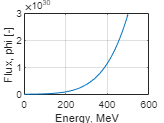

figure(1)
plot(Ei, phi_oV), grid on
xlabel('Energy, MeV')
ylabel('Flux, phi [-]')

## Class 16

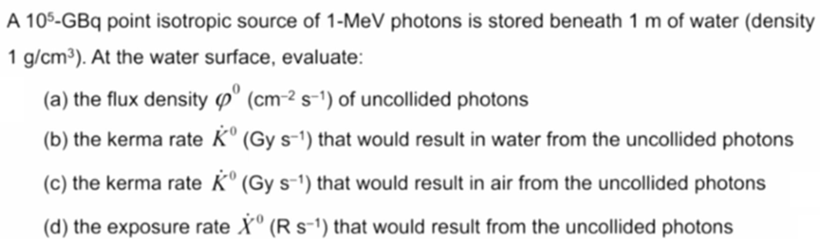

### a) Flux Density

Sp = 1e5 *1e9;          % Bq, #/s
r = 1*100;              % cm
% mu = 1;               % g/cm^2
mu_rh_w = 0.0707;       % LAEC, water; gm/cm^2; AC-C7

A = 4*pi*r^2            % area of sphere; cm^2

A = 1.2566e+05

ph = Sp/A *exp(-mu_rh_w*r)    % flux; #/cm^2.s

ph = 6.7659e+05

### b) Kerma Rate, Water

J_MeV = 1.6e-13;
gm_kg = 1e3;
CF = J_MeV*gm_kg        % conv. factor; Gy /MeV/g

CF = 1.6000e-10

Now, let's find the kerma rate

mu_tr_w = 0.0311;       % E-transfer coeff. for water; cm^2/gm
E = 1;                  % photon energy; MeV
K_r = ph *mu_tr_w *E      % Kerma rate; MeV/g.s

K_r = 2.1042e+04

K_r = K_r *CF           % Gy/s

K_r = 3.3667e-06

### c) Kerma Rate, Air

Check, AC-C7

mu_rh_a = 6.353e-2;         % LAEC, air; gm/cm^2
ph_a = Sp/A *exp(-mu_rh_a*r)  % photon flux, air; #/cm^2.s

ph_a = 1.3859e+06


mu_tr_a = 2.797e-2;     % E-transfer coeff. for air; cm^2/gm
E = 1;                  % photon energy; MeV
K_r = ph_a *mu_tr_a *E    % Kerma rate; MeV/g.s

K_r = 3.8762e+04

K_r = K_r *CF           % Gy/s

K_r = 6.2020e-06

### d) Exposure

From equation 5.30;


$$\dot{X\;} =1\ldotp 835\times {10}^{-8} \;\phi_0 \;\mu_{\mathrm{en}} \;E$$


mu_en_a = 2.789e-2;     % gm/cm^2
C = 1.835e-8;
X_r = C *ph_a *mu_en_a *E

X_r = 7.0925e-04